## Experimental Data

**Author:** Surabhi Joshi

## **Summary**

This script reads in some experimental data and performs exploratory initial statistical analysis to understand how each condition affects the metabolomics before running DFA. 

% download the experimental data and create two tables, one for each
% cancer cell line TU8902 and HCT116.
experimental_data_TU8902 = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ...
'Sheet', 'TU8902');
experimental_data_HCT116 = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ... 
 'Sheet',"HCT116");
% delete row 2 and column 2 from both tables
experimental_data_TU8902.transition = [];
experimental_data_HCT116.transition = [];

%download metabolomics and clusterring data
metabolomics = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ... 
    'Sheet', 'Clustering');
metabolomics(1,:) = [];
metabolomics = table2array(metabolomics);

%have a categorical array of all the conditions present
conditions = ["shNT_no_dox"; "shNT_2d_dox"; "shNT_4d_dox"; "shGOT1_no_dox"; "shGOT1_2d_dox"; "shGOT1_4d_dox"; "shNT_no_dox_media"; "shNT_2d_dox_media"; "shNT_4d_dox_media"; "shGOT1_no_dox_media"; "shGOT1_2d_dox_media"; "shGOT1_4d_dox_media"];

## **Create tables for averages and standard deviations. **

This here is going to take the averages and standard deviations from the original experimental data and fill two new tables with their values. Any NaN will be turned to 0 prior to finding the mean and standard deviations. 

Tabl_average_TU8902 = computeReplicateMetrics(experimental_data_TU8902, 'mean');
Tabl_average_TU8902(227,:) = [];
Tabl_std_TU8902 = computeReplicateMetrics(experimental_data_TU8902, 'stddev');
Tabl_std_TU8902(227,:) = [];
Tabl_average_HCT116 = computeReplicateMetrics(experimental_data_HCT116, 'mean');
Tabl_std_HCT116 = computeReplicateMetrics(experimental_data_HCT116, 'stddev');


## Create a corelation matrix and a following heatmap

Do this by first converting all the NaN values into 0 and then create a corelation matrix of the metabolites using an array of averages.  

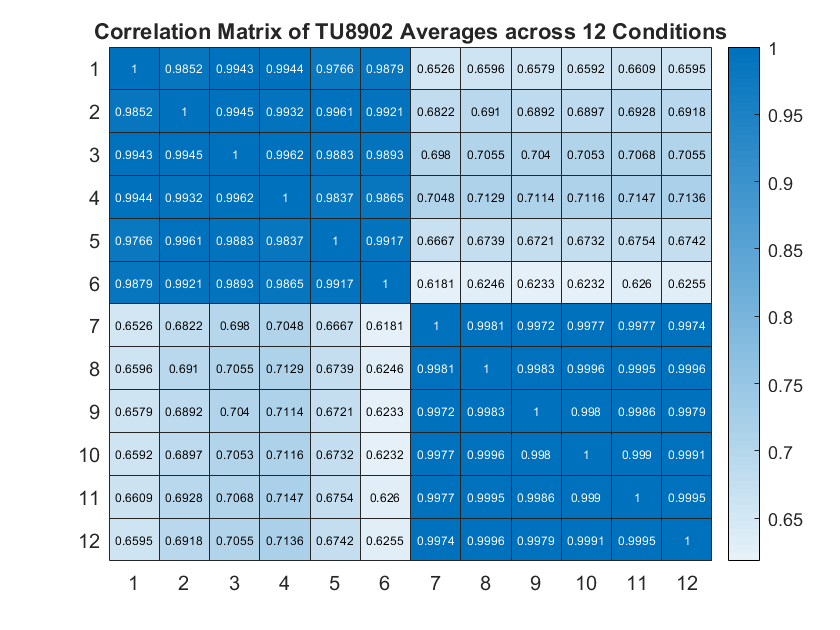

% create arrays from the tables above. 
mean_metabolomic_array_TU8902 = table2array(Tabl_average_TU8902(:,2:end));
std_metabolomic_array_TU8902 = table2array(Tabl_std_TU8902(:,2:end));

mean_metabolomic_array_HCT116 = table2array(Tabl_average_HCT116(:,2:end));
std_metabolomic_array_HCT116 = table2array(Tabl_std_HCT116(:,2:end));

%Convert all the NaN values to 0
mean_metabolomic_array_TU8902(isnan(mean_metabolomic_array_TU8902)) = 0;
mean_metabolomic_array_HCT116(isnan(mean_metabolomic_array_HCT116)) = 0;

%r matrix and its heatmap - for the 12 conditions
averageCorrMat_TU8902 = corrcoef(mean_metabolomic_array_TU8902);
figure (1);
heatmap(averageCorrMat_TU8902);
title 'Correlation Matrix of TU8902 Averages across 12 Conditions';

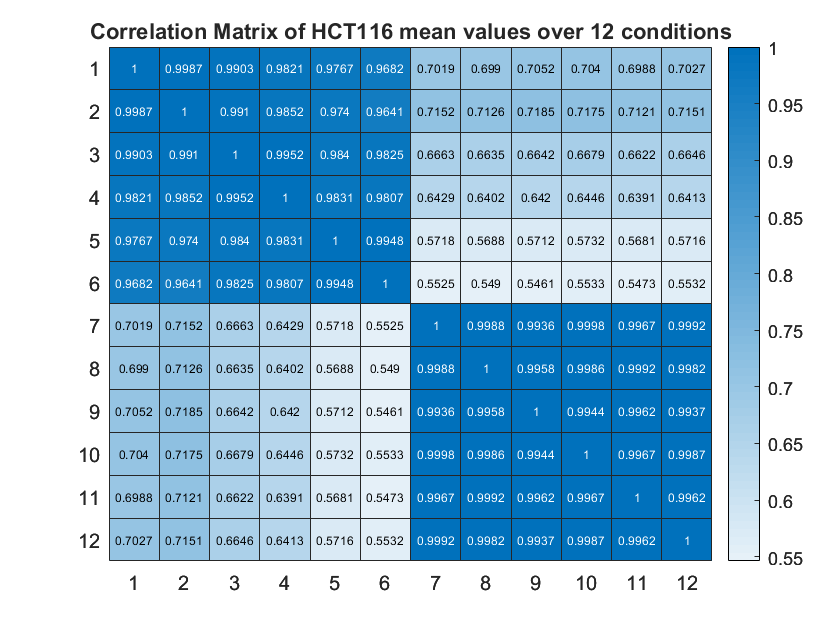


averageCorrMat_HCT116 = corrcoef(mean_metabolomic_array_HCT116);
figure (2);
heatmap(averageCorrMat_HCT116);
title 'Correlation Matrix of HCT116 mean values over 12 conditions';

% create r matrix and heatmaps for the metabolomics
corrmat = zeros(12);
for i = 1:size(mean_metabolomic_array_TU8902, 1)
    metabolite = mean_metabolomic_array_TU8902(i, :);
    tmp = corr(metabolite);
    corrmat(:, i) = diag(tmp);
end 
% NOTE: Running this gives a matrix of NaNs.

## Create the correlation matrix, CV 

%CV matrix
CV_TU8902 = std_metabolomic_array_TU8902 ./ mean_metabolomic_array_TU8902;
CV_HCT116 = std_metabolomic_array_HCT116 ./ mean_metabolomic_array_HCT116;

## Create heatmaps to visually understand the standard deviations and averages. 

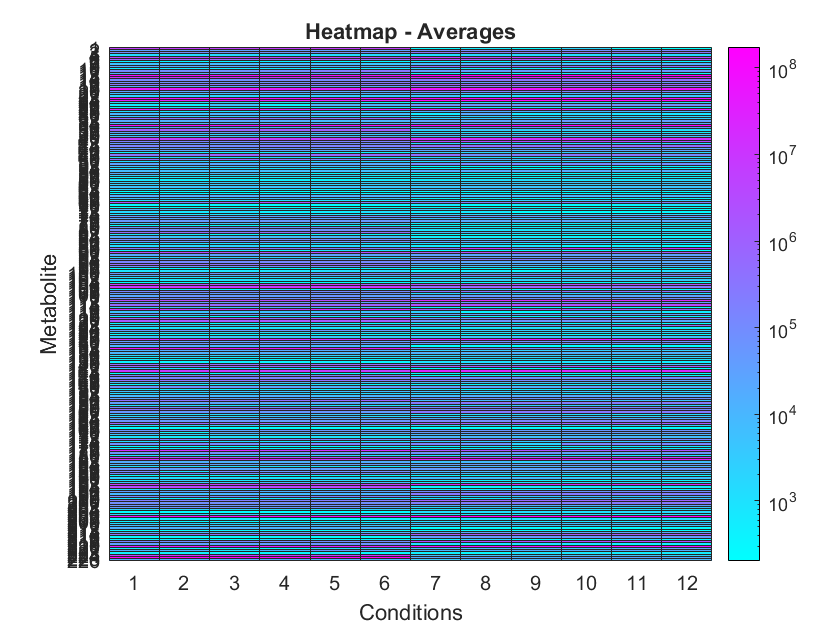

figure (3);
heatmap(mean_metabolomic_array_TU8902, 'ColorScaling', 'log');
xlabel('Conditions');
ylabel('Metabolite');
title('Heatmap - Averages');
colormap 'cool';

## Scatterplots of the mean and standard deviations

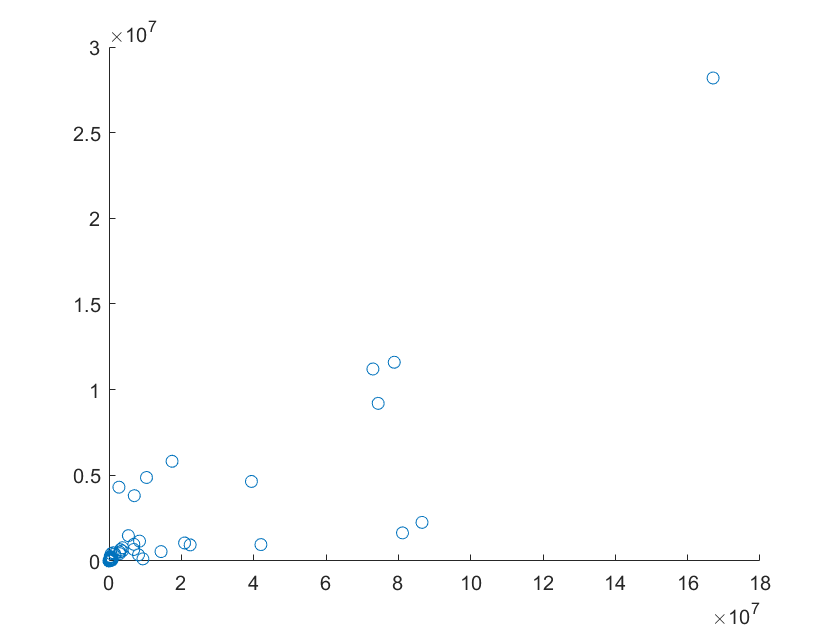

%scatterplots of mean and std
figure (4);
scatter(mean_metabolomic_array_TU8902(:,1), std_metabolomic_array_TU8902(:,1));

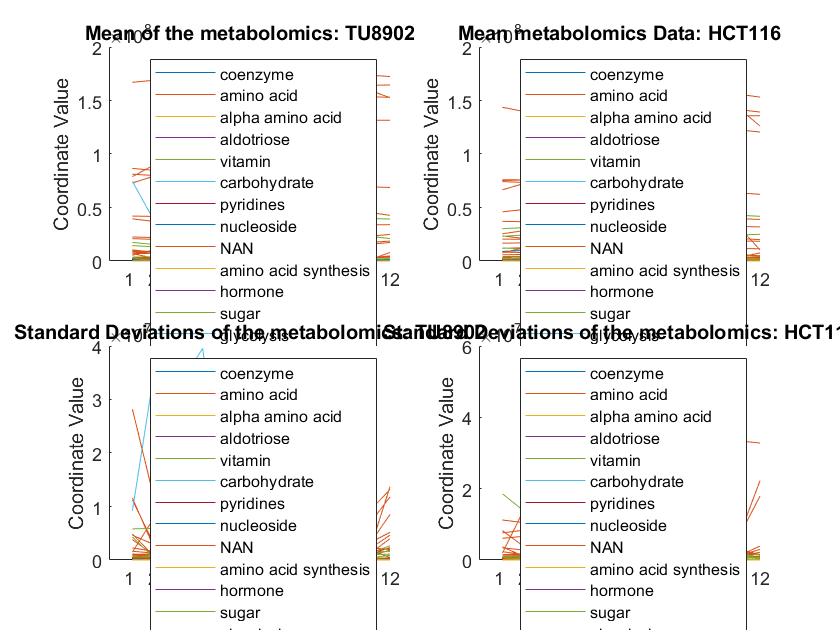


figure (5);
%This for loop finds all the amino acid metabolites. 

aminoAcidIndex = []; 
for i = 1:226
    if strcmpi(metabolomics(i,2),'amino acid')
        aminoAcidIndex = [aminoAcidIndex; i];
    end
end

parallelcoords(mean_metabolomic_array_TU8902(aminoAcidIndex,:), 'group', metabolomics(aminoAcidIndex,1), 'Labels', conditions);
title('Mean Values - TU9802 Amino Acids')

figure (5);
subplot(2,2,1);
parallelcoords(mean_metabolomic_array_TU8902, 'group', metabolomics(:,2));
title('Mean of the metabolomics: TU8902');

subplot(2,2,2);
parallelcoords(mean_metabolomic_array_HCT116, 'group', metabolomics(:,2));
title('Mean metabolomics Data: HCT116');

subplot(2,2,3);
parallelcoords(std_metabolomic_array_TU8902, 'group', metabolomics(:,2));
title('Standard Deviations of the metabolomics: TU8902');

subplot(2,2,4);
parallelcoords(std_metabolomic_array_HCT116, 'group', metabolomics(:,2));
title('Standard Deviations of the metabolomics: HCT116');

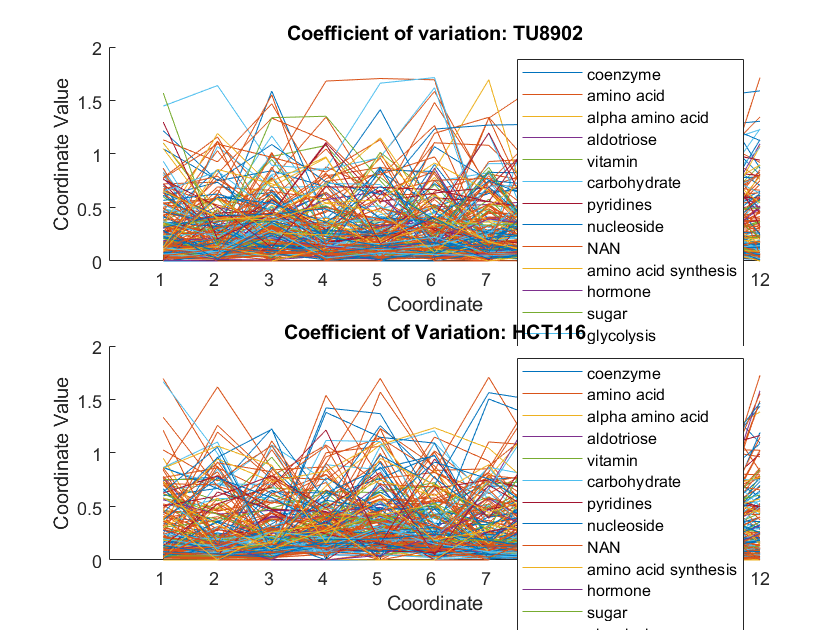

% plots of the coefficient of variation 
figure (6);
subplot(2,1,1);
parallelcoords(CV_TU8902, 'group', metabolomics(:,2));
title('Coefficient of variation: TU8902');

subplot(2,1,2);
parallelcoords(CV_HCT116, 'group', metabolomics(:,2))
title('Coefficient of Variation: HCT116');

## Hisograms of the mean and standard deviations

%histograms of mean and std

## DFA Filter 1: CV thresholds

## DFA Filter 2: NaN metabolomics

This filter will find all of the metabolites that have no corresponding averages: no data for any of the 12 conditions. This filter will parse through the averages array and if every single column for that specific row equals 0, then the metabolite name will be added to the a new array. 

% array for TU8902 and HCT116
no_data_TU9802 = [];
no_data_HCT116 = [];
for i = 1:226
    if mean_metabolomic_array_TU8902(i,:) == 0
        no_data_TU9802 = [no_data_TU9802; metabolomics(i)];
    end
    
    if mean_metabolomic_array_HCT116(i,:) == 0
        no_data_HCT116 = [no_data_HCT116; metabolomics(i)];
    end
end

## Use Filter 2 to create new data sheet

Now, we will use the Filter 2 to create an excel sheet for DFA. 

This for loop will delete the metabolomics that are mentioned in filter 2

for i = 1:size(no_data_HCT116)
    for j = 1:size(Tabl_average_HCT116)
       if strcmpi(no_data_HCT116{i},Tabl_average_HCT116{j,"metabolite"})
       %if cellfun(@isequal, no_data_HCT116(i), Tabl_average_HCT116(j,"metabolite")) 
       Tabl_average_HCT116(j,:) = [];
       end 
    end
end

Row index exceeds table dimensions.

Now, export the final table out as an excel sheet. 

%{
filename = 'Filter 2: HCT116 Cancer.xlsx';
writetable(Tabl_std_HCT116,filename);
%}